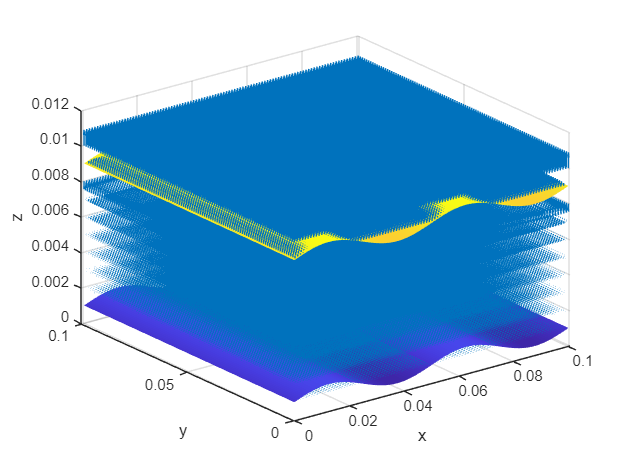

% A computational tool to calculate the capacitance of a 3D rectangular 
% prism composed of two plates parallel to x-y plane

clear;
clc;

% Grid dimensions - number of points
xdim=100;
ydim=100;
zdim=10;
dx = 0.001; % grid spacing (1 mm, arbitrary scaling)
dy = 0.001;
dz = 0.001;

% Initialize voltage matricies
V_now=zeros(xdim+1, ydim+1, zdim+1);

% Initialize boundary conditions (capacitor plates)

% Define functions for boundary conditions (non-parallel capacitor plates)
x = (0:xdim) * dx;
y = (0:ydim) * dy;
[X, Y] = meshgrid(x, y);

% flat parallel plates
% V_top = 30
% Zsurf_top = zdim*dz*ones(xdim+1, ydim+1);
% Zsurf_bottom = 0*ones(xdim+1, ydim+1);
% V_now(:, :, 1) = Zsurf_bottom;          % bottom plate 0V (bottom plate is z = 0)
% V_now(:, :, zdim+1) = V_top;    % top plate

% sinusodal boundary conditions
A_top  = 0.0005;                 % amplitude (m)
z0_top = 0.009;                  % mean height (m)
kx_top = 4*pi / x(end);         % wavelength fits domain
Zsurf_top = z0_top + A_top * sin(kx_top * X);
k_surf_top = round(Zsurf_top/dz) + 1;
V_top = 30;
for i = 1:xdim+1
    for j = 1:ydim+1
        k = k_surf_top(j, i);
        if k >= 1 && k <= zdim+1
            V_now(i, j, k) = V_top;
        end
    end
end

A_bottom  = 0.0005;                 % amplitude (m)
z0_bottom = 0.001;                  % mean height (m)
kx_bottom = 4*pi / x(end);         % wavelength fits domain
Zsurf_bottom = z0_bottom + A_bottom * sin(kx_bottom * X);
k_surf_bottom = round(Zsurf_bottom/dz) + 1;
for i = 1:xdim+1
    for j = 1:ydim+1
        k = k_surf_bottom(j, i);
        if k >= 1 && k <= zdim+1
            V_now(i, j, k) = 0;
        end
    end
end

% Iteration counter
iter=0;

% Calculation of maximum error between V_now and V_prev at all points
% by setting the applied voltage for only V_now, we have made V_no and
% V_prev different, hence error will be greater than zero and the program
% will enter the while loop following this command.
V_prev = V_now;
error=1;%max(max(abs(V_now-V_prev)));

% Fix the boundary conditions and only solve for between plates
k_surf_top = round(Zsurf_top/dz) + 1;
k_surf_bottom = round(Zsurf_bottom/dz) + 1;
isFixed = false(xdim+1, ydim+1, zdim+1);
solve = false(xdim+1, ydim+1, zdim+1);
for i = 1:xdim+1
    for j = 1:ydim+1
        kb = k_surf_bottom(j,i);
        kt = k_surf_top(j,i);

        if kb >= 1 && kb <= zdim+1
            isFixed(i,j,kb) = true;
            V_prev(i,j,kb) = 0;
        end
        if kt >= 1 && kt <= zdim+1
            isFixed(i,j,kt) = true;
            V_prev(i,j,kt) = V_top;
        end
        if kb < kt
            solve(i,j,kb+1:kt-1) = true;
        end
    end
end

% Iteration loop
while(error>0.01)% Run this until convergence
    
    iter=iter+1; % Iteration counter increment
    
    % Updating present iteration using 6 point Central diffrence (Taylor series) form
    % of Laplace equation obtained using Finite Difference method
    for i = 2:xdim
        for j = 2:ydim
            for k = 2:zdim
                if solve(i,j,k) && ~isFixed(i,j,k)
                    V_now(i, j, k) = (V_prev(i-1, j, k)+V_prev(i+1, j, k)+V_prev(i, j-1, k)+V_prev(i, j+1, k)+V_prev(i, j, k-1)+V_prev(i, j, k+1))/6;
                end
            end
        end
    end
    % enforce boundary conditions on each iteration
    % V_now(:,:,1)       = 0;
    % V_now(:,:,zdim+1)  = V_top

    error=max(max(abs(V_now(:)-V_prev(:)))); % Calculate the maximum error between previous and current iteration at all points
    V_prev=V_now; % Updating previous iteration matrix to the last iteration performed
    
    % Add visualization from BDE solver here if have time
end

% Plot the electric field distribution
figure;
[ex, ey, ez]=gradient(V_now, dx, dy, dz); % E, electric field
ex = -ex;
ey = -ey;
ez = -ez;
[x, y, z] = meshgrid((0:size(V_now, 2)-1)*dx, (0:size(V_now,1)-1)*dy, (0:size(V_now,3)-1)*dz);
quiver3(x, y, z, ex, ey, ez); % quiver3 command creates a plot of E=-grad(V)
hold on
xlabel('x'); ylabel('y'); zlabel('z')

surf(X, Y, Zsurf_top)
surf(X, Y, Zsurf_bottom)
xlabel('x'); ylabel('y'); zlabel('z')
shading interp
hold off


% Calculate capacitance
epsilon0 = 8.854e-12;           % Air permittivity
% Ex_top = -ex(:, :, end-1);      % x component of field just below the top (charged) plate
% Ey_top = -ey(:, :, end-1);      % y component of field just below the top (charged) plate
% Ez_top = -ez(:,:,end-1);        % z component of field just below the top (charged) plate
Ex_top = zeros(xdim+1, ydim+1);
Ey_top = zeros(xdim+1, ydim+1);
Ez_top = zeros(xdim+1, ydim+1);
for i = 1:xdim+1
    for j = 1:ydim+1
        k = k_surf_top(j, i);
        if k >= 1 && k <= zdim+1
            Ex_top(i, j) = -ex(i, j, k);
            Ey_top(i, j) = -ey(i, j, k);
            Ez_top(i, j) = -ez(i, j, k);
        end
    end
end
rho = epsilon0 * Ez_top;        % surface charge density (C/m^2)
C_fdm = sum(sum(rho./V_top)*dx*dy(:))

C_fdm = -3.6312e-11

% Q_top = sum(rho)*dx*dy;         % integrate over plate area
% Q_tot = sum(Q_top(:));
% C_fdm = Q_tot/V_top
A = (xdim*dx) * (ydim*dy); % plate area
C_theoretical = epsilon0 * A / (zdim*dz) % for testing purposes

C_theoretical = 8.8540e-12